clc
clear
close all;

%Debugging
cases = [
    %Debugging Case 1: thin, tapered, no twist
    100, 2*pi, 2*pi,  8, 10, 0, 0, 5*pi/180, 5*pi/180, 5;
    
    %Debugging Case 2: thin, rectangular, no twist
    100, 2*pi, 2*pi, 10, 10, 0, 0, 5*pi/180, 5*pi/180, 5;
    
    %Debugging Case 3: thick, tapered, aero. + geometric twist
    100, 6.3,  6.5,   8, 10, 0, -2*pi/180, 5*pi/180, 7*pi/180, 5];

caseNames = {
    'Thin tapered (ct=8, cr=10), no twist';
    'Thin rectangular (ct=cr=10), no twist';
    'Thick tapered (ct=8, cr=10), aero.+geom. twist'};

%Provided values
e_exp = [0.9430; 0.9227; 0.9795];
cL_exp = [0.4534; 0.4402; 0.6674];
cDi_exp = [0.0062; 0.0067; 0.0130];

nCases = size(cases,1);

%store
e_code = zeros(nCases,1);
cL_code = zeros(nCases,1);
cDi_code = zeros(nCases,1);

%PLLT Run for each case
for k = 1:nCases
    b = cases(k,1);
    a0_t = cases(k,2);
    a0_r = cases(k,3);
    c_t = cases(k,4);
    c_r = cases(k,5);
    aero_t = cases(k,6);
    aero_r = cases(k,7);
    geo_t = cases(k,8);
    geo_r = cases(k,9);
    N = cases(k,10);

    [e_code(k), cL_code(k), cDi_code(k)] = PLLT(b,a0_t,a0_r,c_t,c_r,aero_t,aero_r,geo_t,geo_r,N);
end

%Table build
results = table(caseNames, e_code, e_exp,  e_code - e_exp, ...
    cL_code, cL_exp, cL_code - cL_exp, cDi_code, cDi_exp, cDi_code - cDi_exp, ...
    'VariableNames', {'Case','e_code','e_expected','e_error', ...
    'cL_code','cL_expected','cL_error','cDi_code','cDi_expected','cDi_error'});
%Output
results

results = 3×10 table
                           Case                           e_code     e_expected      e_error      cL_code    cL_expected     cL_error     cDi_code     cDi_expected     cDi_error 
    __________________________________________________    _______    __________    ___________    _______    ___________    __________    _________    ____________    ___________

    {'Thin tapered (ct=8, cr=10), no twist'          }    0.94299       0.943      -1.2531e-05    0.45342      0.4534       1.9779e-05    0.0062458       0.0062        4.5794e-05
    {'Thin rectangular (ct=cr=10), no twist'         }    0.92269      0.9227      -9.7539e-06    0.4

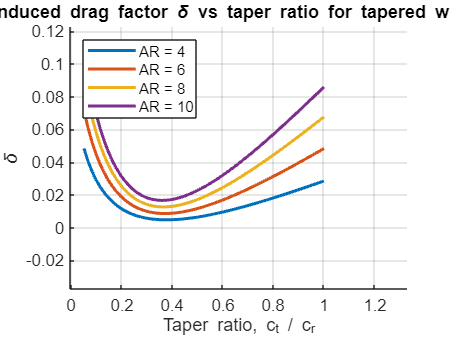

%Input + Plotting
a0_r = 2*pi; %thin airfoil lift slope (same at root & tip)
a0_t = 2*pi;
aero_r = 0; 
aero_t = 0; %(no twist)
alpha = deg2rad(5); %some small geometric AoA
geo_r = alpha; geo_t = alpha; %no geometric twist

Nterms = 40; %odd terms ONLY-
b = 2.0; %arbitrary span

AR_list = [4 6 8 10]; %aspect ratios for curves
lambda = linspace(0.05,1.0,60); %taper ratio ct/cr

delta = zeros(numel(AR_list), numel(lambda));

for k = 1:numel(AR_list)
    AR = AR_list(k);
    S = b^2 / AR; %area for AR

    for i = 1:numel(lambda)
        lam = lambda(i); %taper ratio

        %trapezoid with given AR and taper
        c_r = 2*S / (b*(1+lam)); %S = 0.5*(cr+ct)*b
        c_t = lam*c_r;

        %call PLLT
        [e,cL,cDi] = PLLT(b,a0_t,a0_r,c_t,c_r,aero_t,aero_r,geo_t,geo_r,Nterms);

        %induced-drag factor
        delta(k,i) = 1/e - 1;
    end
end

%Plotting
figure; hold on; grid on;
colors = lines(numel(AR_list));
for k = 1:numel(AR_list)
    plot(lambda, delta(k,:),'LineWidth',1.8,'Color',colors(k,:));
end
xlabel('Taper ratio, c_t / c_r');
ylabel('\delta');
title('Induced \delta vs taper ratio');
legend('AR = 4','AR = 6','AR = 8','AR = 10','Location','NorthWest');

function [e, c_L, c_Di] = PLLT(b,a0_t,a0_r,c_t,c_r,aero_t,aero_r,geo_t,geo_r,N)
    %halfspan points
    i = (1:N).';
    theta = i*pi/(2*N);
    eta = cos(theta); %nondimensional span
    % Lift slope
    a0 = a0_r + (a0_t - a0_r).*eta;
    %Chord
    c = c_r + (c_t - c_r).*eta;
    %Zero-lift angle
    alphaL0 = aero_r + (aero_t - aero_r).*eta;
    %Geometric AoA(twist + AC AoA)
    alphaG  = geo_r + (geo_t  - geo_r).*eta;

    %linear system for A_(2j-1)
    % Unknowns
    A_mat = zeros(N);       %coefficient matrix
    rhs = alphaG - alphaL0;  %right-hand side

    for ii = 1:N
        for jj = 1:N
            n = 2*jj - 1; %odd index
            sin_nth = sin(n*theta(ii));
            term1 = 4*b/(a0(ii)*c(ii))*sin_nth;
            term2 = n*sin_nth / sin(theta(ii));
            A_mat(ii,jj) = term1 + term2;
        end
    end

    %Solving for A_(2j-1)
    A = A_mat\rhs; %column vector length N
    %Wing lift & induced drag coefficients
    %S and AR
    S = 0.5*(c_r + c_t)*b; %trapezoidal wing area
    AR = b^2 / S;
    % A1 is n=1
    A1 = A(1);

    %Lift coefficient
    c_L = pi*AR*A1;

    %Induced drag coefficient(odd n only)
    c_Di = 0.0;
    for jj = 1:N
        n = 2*jj - 1;
        c_Di = c_Di + n*A(jj)^2;
    end
    c_Di = pi * AR * c_Di;

    %Span efficiency factor
    e = c_L^2 /(pi*AR*c_Di);
end